# Element Stiffness Matrix and Body Load Vector for the Reissner-Mindlin Plate using the Assumed Natural Strain

Returns the element stiffness matrix and body load vector for the Reissner-Mindlin plate when using the Assumed Natural Strain (ANS) method for the representation of the shear forces, see the following figure:

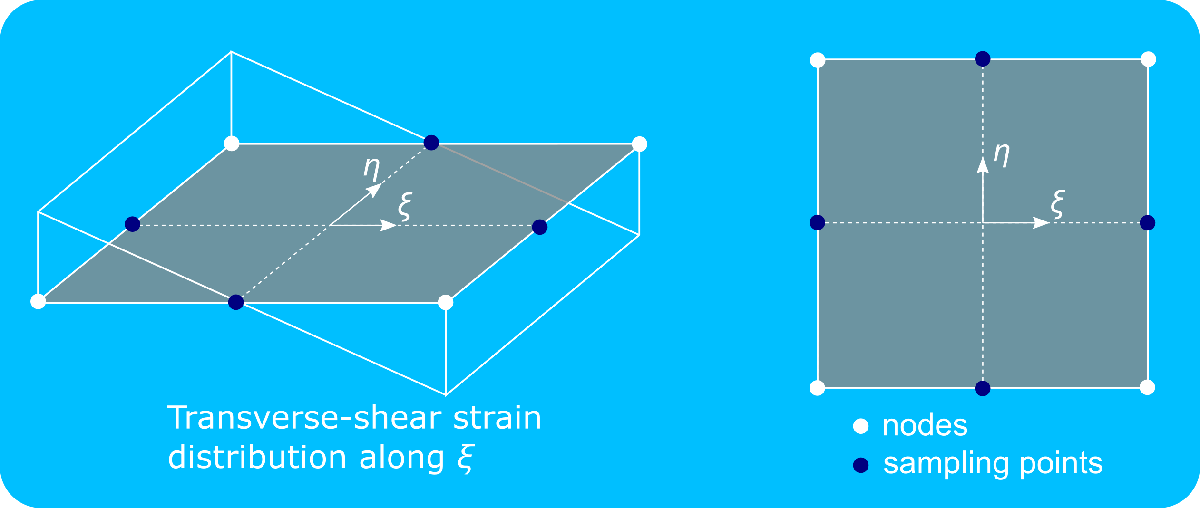

function [Ke, Fe] = computeElementStiffMatrixandForceVectorReissnerMindlinPlateANS ...
    (X, computeBasisFunctionsAndDerivs, propStr)

## Function Description

Computation of the element stiffness matrix for an element based on the 2D Reissner-Mindlin plate theory with three degrees of freedom per node $\left(w,\beta_x ,\beta_y \right)$, the vertical deflection and two rotations of the plate's cross section around the X- and the Y-axis, respectively, where reduced integration is used for integrating the terms $\frac{\partial w}{\partial X}, \frac{\partial w}{\partial Y}$ in the stiffness matrix.

**                                                   Input :**

                                                          `X` : Array containing the nodal coordinates of the nodes in the element

`computeBasisFunctionsAndDerivs` : Function handle to the computation of the basis functions

                                             `propStr` : Structure containing the following fields,

                                                                    .`t` : Thickness of the shell

                                                              .`pBar` : Distributed load on the shell

                                                            .`mxBar` : Distributed moment on the beam around x-axis

                                                            .`myBar` : Distributed moment on the beam around y-axis

                                                                    .`E` : Young's modulus

                                                                  .`nu` : Poisson's ratio

                                                                    .`G` : Shear modulus

                                                                    .`D` : Plate's stiffness

                                                            .`alpha` : Shear correction factor

**                                               Output :**

                                                       `Ke` : Element stiffness matrix of a Reissner-Mindlin shell

                                                       `Fe` : Element force vector of a Reissner-Mindlin shell

## Function Implementation

### Input validation

    arguments
        X (:, 2) double
        computeBasisFunctionsAndDerivs (1, 1) function_handle
        propStr (1, 1) {mustHaveReissnerMindlinPlateProperties}
    end

### Check input

    if strcmp(func2str(computeBasisFunctionsAndDerivs), ...
            "computeBilinearBasisFunctionsAndFirstDerivatives")
        numNodesEl = 4;
    elseif strcmp(func2str(computeBasisFunctionsAndDerivs), ...
            "computeBiquadraticBasisFunctionsAndFirstDerivatives")
        numNodesEl = 9;
    else
        error("Input 'computeBasisFunctionsAndDerivs' is defined as %s but only " + ...
            "values 'computeBilinearBasisFunctionsAndFirstDerivatives' and " + ...
            "'computeBiquadraticBasisFunctionsAndFirstDerivatives' are supported", ...
            computeBasisFunctionsAndDerivs);
    end
    if numNodesEl ~= numel(X(:, 1))
        error("It is provided an element with %d nodes and the function handle %s " + ...
            "for the computation of the basis functions", numel(X(:, 1)), ...
            func2str(computeBasisFunctionsAndDerivs));
    end

### Initialize output

    Ke = zeros(3*numNodesEl);
    Fe = zeros(3*numNodesEl, 1);

### Material matrix

    C = [propStr.alpha*propStr.G*propStr.t 0                                 0                    0                     0
         0                                 propStr.alpha*propStr.G*propStr.t 0                    0                     0
         0                                 0                                 propStr.D            propStr.nu*propStr.D  0
         0                                 0                                 propStr.nu*propStr.D propStr.D             0
         0                                 0                                 0                    0                     propStr.D/2*(1 - propStr.nu)];

### Get Gauss points and weights

Integration of the part involving the terms $\frac{\partial w}{\partial X}, \frac{\partial w}{\partial Y}$ using full integration

    [xiGP, GWxi] = getGaussPointsAndWeightsOverUnitDomain(2);
    [etaGP, GWeta] = getGaussPointsAndWeightsOverUnitDomain(2);

### Reconstruction of the shear strains using a linear interpolation at the opposite edges

    xiTPXiDir = [0 0];
    etaTPXiDir= [-1 1];
    xiTPEtaDir = [-1 1];
    etaTPEtaDir= [0 0];
    numPtsDir = numel(xiTPXiDir);
    BAuxMtx = zeros(numNodesEl, 3*numNodesEl);

### Loop over all the sampling points along the xi-direction

    for ii = 1:numel(xiTPXiDir)

#### Basis functions at the sampling point along xi-direction

        [dN, ~] = computeBasisFunctionsAndDerivs(xiTPXiDir(ii), etaTPXiDir(ii));

#### Setup of the Jacobian matrix along xi-direction

        Jvct = zeros(2, 1);
        for kk = 1:4
            Jvct(1, 1) = Jvct(1, 1) + dN(kk, 2)*X(kk, 1);
            Jvct(2, 1) = Jvct(2, 1) + dN(kk, 2)*X(kk, 2);
        end

#### Setup the B-operator matrix along the xi-direction

        for kk = 1:numNodesEl
            BAuxMtx(ii, 3*kk - 2) = dN(kk, 2);
            BAuxMtx(ii, 3*kk - 1) = -dN(kk, 1)*Jvct(2, 1);
            BAuxMtx(ii, 3*kk) = dN(kk, 1)*Jvct(1, 1);
        end

    end

### Loop over all the sampling points along the eta-direction

    for ii = 1:numel(xiTPEtaDir)

#### Basis functions at the sampling point along eta-direction

        [dN, ~] = computeBasisFunctionsAndDerivs(xiTPEtaDir(ii), etaTPEtaDir(ii));

#### Setup of the Jacobian matrix along eta-direction

        Jvct = zeros(2, 1);
        for kk = 1:numNodesEl
            Jvct(1, 1) = Jvct(1, 1) + dN(kk, 3)*X(kk, 1);
            Jvct(2, 1) = Jvct(2, 1) + dN(kk, 3)*X(kk, 2);
        end

#### Setup the B-operator matrix along the eta-direction

        for kk = 1:numNodesEl
            BAuxMtx(ii + numPtsDir, 3*kk - 2) = dN(kk, 3);
            BAuxMtx(ii + numPtsDir, 3*kk - 1) = -dN(kk, 1)*Jvct(2, 1);
            BAuxMtx(ii + numPtsDir, 3*kk) = dN(kk, 1)*Jvct(1, 1);
        end
    end

### Loop over all the Gauss points

    for jj = 1:height(GWeta)
        for ii = 1:height(GWxi)

#### Basis functions at the Gauss point

            [dN, ~] = computeBasisFunctionsAndDerivs(xiGP(ii), etaGP(jj));

#### Shape function matrix at the Gauss point

%             Nmtx = [dN(1, 1) 0         0        dN(2, 1) 0         0        dN(3, 1) 0         0        dN(4, 1) 0         0
%                     0        dN(1, 1)  0        0        dN(2, 1)  0        0        dN(3, 1)  0        0        dN(4, 1)  0
%                     0        0         dN(1, 1) 0        0         dN(2, 1) 0        0         dN(3, 1) 0        0         dN(4, 1)];
            Nmtx = zeros(3, 3*numNodesEl);
            for kk = 1:numNodesEl
                Nmtx(1, 3*kk - 2) = dN(kk, 1);
                Nmtx(2, 3*kk - 1) = dN(kk, 1);
                Nmtx(3, 3*kk) = dN(kk, 1);
            end

#### Jacobian matrix at the Gauss point

            Jmtx = zeros(2);
            for kk = 1:numNodesEl
                Jmtx(1, 1) = Jmtx(1, 1) + dN(kk, 2)*X(kk, 1);
                Jmtx(1, 2) = Jmtx(1, 2) + dN(kk, 2)*X(kk, 2);
                Jmtx(2, 1) = Jmtx(2, 1) + dN(kk, 3)*X(kk, 1);
                Jmtx(2, 2) = Jmtx(2, 2) + dN(kk, 3)*X(kk, 2);
            end

#### Derivatives of the basis functions with respect to the physical space at the Gauss point

            dNdX = transpose(Jmtx\transpose(dN(:, 2:3)));

#### Basis functions matrix for the discretization of the transverse-shear strains at the Gauss point

            NTmtx = [1 - etaGP(jj), 1 + etaGP(jj), 0,            0
                     0,             0,             1 - xiGP(jj), 1 + xiGP(jj)];

#### Hybrid B-operator matrix at the Gauss point where the discretization of the shear strains is enhanced

            Bmtx = zeros(5, 3*numNodesEl);
            Bmtx(1:2, :) = Jmtx\NTmtx*BAuxMtx;
            for kk = 1:numNodesEl
                Bmtx(3, 3*kk) = dNdX(kk, 1);
                Bmtx(4, 3*kk - 1) = -dNdX(kk,2);
                Bmtx(5, 3*kk - 1) = -dNdX(kk, 1);
                Bmtx(5, 3*kk) = dNdX(kk,2);
            end

#### Computation and assembly of the element stiffness matrix and body load vector to the global counterparts

            Ke = Ke + transpose(Bmtx)*C*Bmtx*det(Jmtx)*GWxi(ii)*GWeta(jj);
            Fe = Fe + transpose(Nmtx)*[propStr.pBar; propStr.mxBar; propStr.myBar]* ...
                det(Jmtx)*GWxi(ii)*GWeta(jj);

        end

    end

end